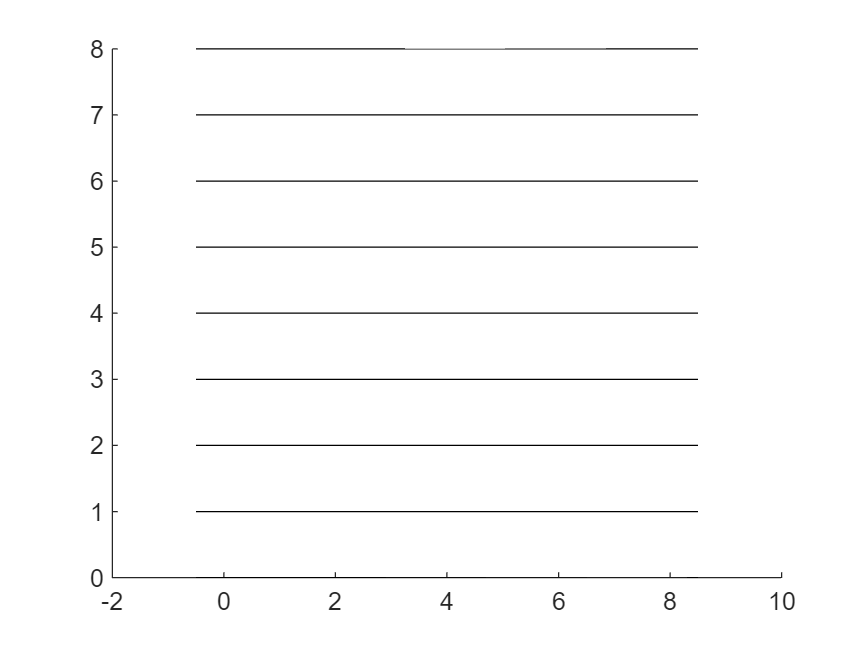

clc,clear,close all
a=1; %平行线间距
l=a/2; %针长
x=repmat([-0.5;8.5],1,9);
y=repmat(linspace(0,8,9),2,1);
line(x,y,'Color','black')
hold on %固定图像框

n=1000; %投针次数
sz=25;
countNeedle=0; %初始化计数器

% 预分配内存，加快程序运行速度
needleXL=zeros(1,n);
needleYL=zeros(1,n);
theta=zeros(1,n);
needleXR=zeros(1,n);
needlemidX=zeros(1,n);
needleYR=zeros(1,n);
needlemidY=zeros(1,n);
my_pi=zeros(1,n);

parfor i=1:n % 使用parfor进行并行计算
    needleXL(i)=8*rand; %随机生成投针的起始点横坐标
    needleYL(i)=8*rand; %随机生成投针的起始点纵坐标
    theta(i)=pi*rand; %随机生成针与线的夹角
    needleXR(i)=needleXL(i)+l*cos(theta(i)); %计算投针的另一端点横坐标
    needleYR(i)=needleYL(i)+l*sin(theta(i)); %计算投针的另一端点纵坐标
    needlemidX(i)=0.5*(needleXL(i)+needleXR(i));
    needlemidY(i)=0.5*(needleYR(i)+needleYL(i));
    
    if fix(needleYL(i))~=fix(needleYR(i)) %判断针与线是否相交 
        plot([needleXL(i),needleXR(i)],[needleYL(i),needleYR(i)],'Color','r','LineWidth',1) %画出投针的位置
        scatter(needlemidX(i),needlemidY(i),sz,'red','filled')
        countNeedle=countNeedle+1; %记录针与线相交次数
    else 
        plot([needleXL(i),needleXR(i)],[needleYL(i),needleYR(i)],'Color','#0072BD','LineWidth',1) %画出投针的位置
        scatter(needlemidX(i),needlemidY(i),sz,[0 0.4470 0.7410],'filled')
    end
    my_pi(i)=i/countNeedle;
end

错误: 变量 'countNeedle' 可能本来要用作归约变量，但实际上是未初始化的临时变量。有关详细信息，请参阅 MATLAB 中的并行 for 循环，“用作 Reduction 变量的临时变量”。


xlim([-0.5,8.5])
ylim([-0.5,8.5])
set(gca,'XColor','white') 
set(gca,'YColor','white') 
set(gca,'Color','white') 

piEst=n/countNeedle; %计算pi的近似值
disp(['共投针',num2str(n),'次, ','其中与平行线相交',num2str(countNeedle),'次, ','Pi的估计值为',num2str(piEst),'.'])
figure
plot(my_pi,'LineWidth',1)
line([0,n],[pi,pi],'LineWidth',2,'LineStyle','--','color','r')

legend({'Estimated','Exact'})
legend('Position',[0.71568,0.14102,0.16964,0.067857])
title('Estimated Value of Pi by Buffon''s Needle Problem')
xlabel('Number of Casting')
ylabel('Estimated Value ')

RE=abs(my_pi-3.14159265358979323846)/3.14159265358979323846;
figure
plot(RE,'LineWidth',1,'Color','#7E2F8E')
legend('Relative Error')
title('The Relative Error Distribution of Buffon''s Needle Problem')
xlabel('Number of Casting')
ylabel('Relative Error')
